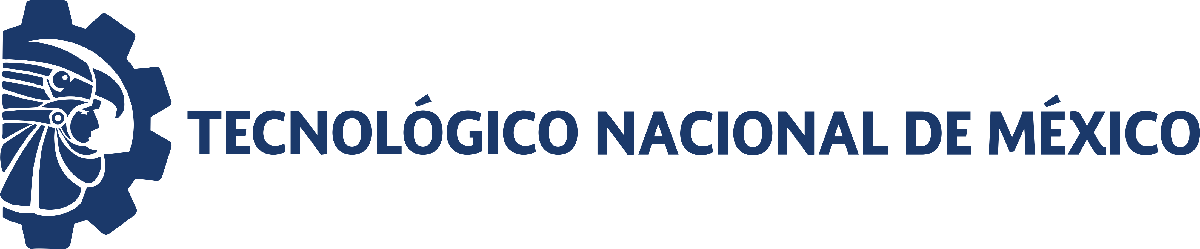                                 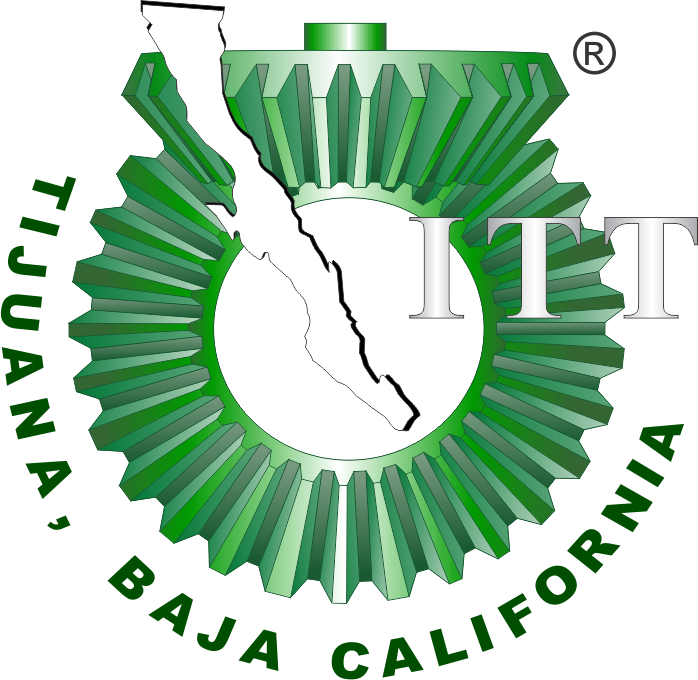

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

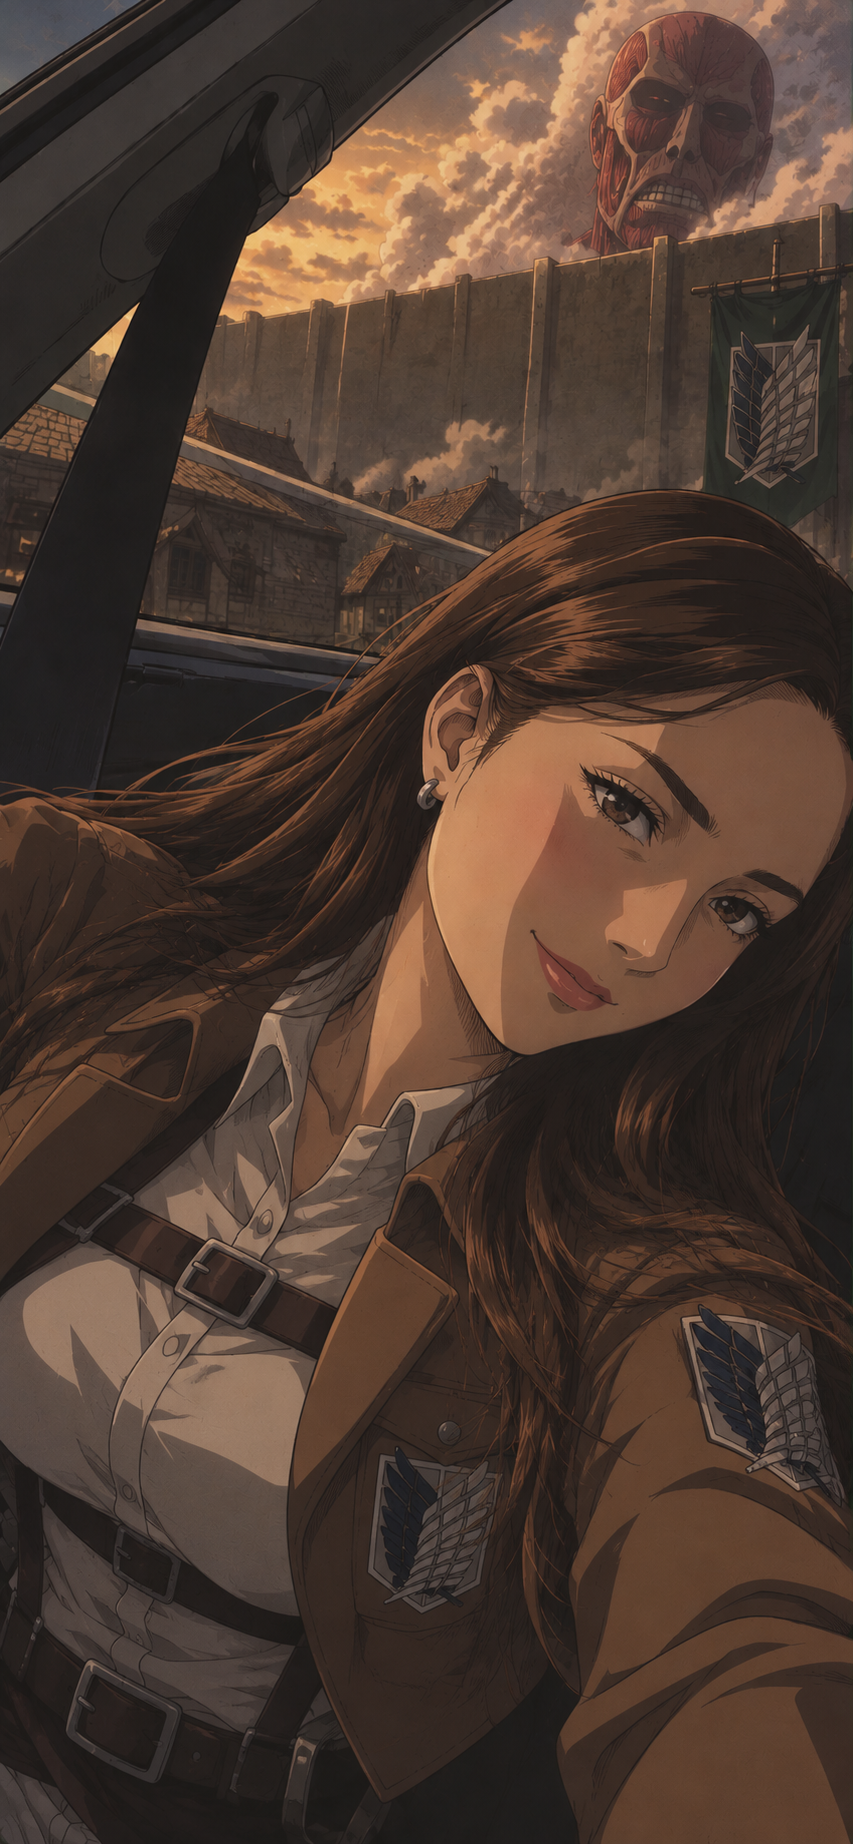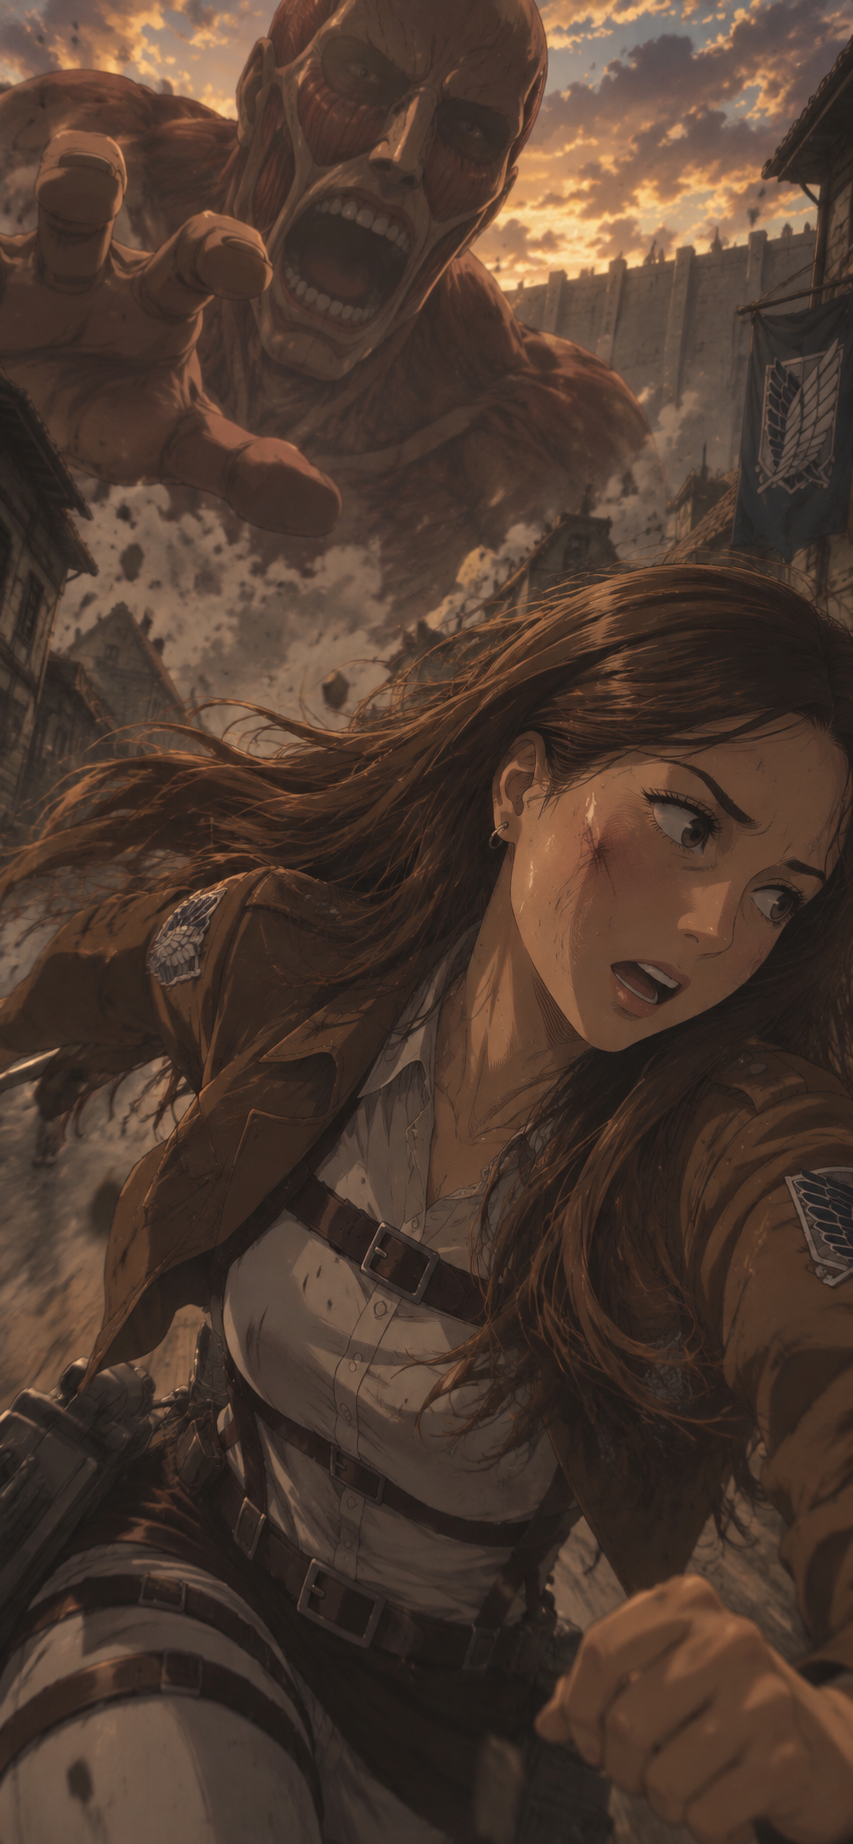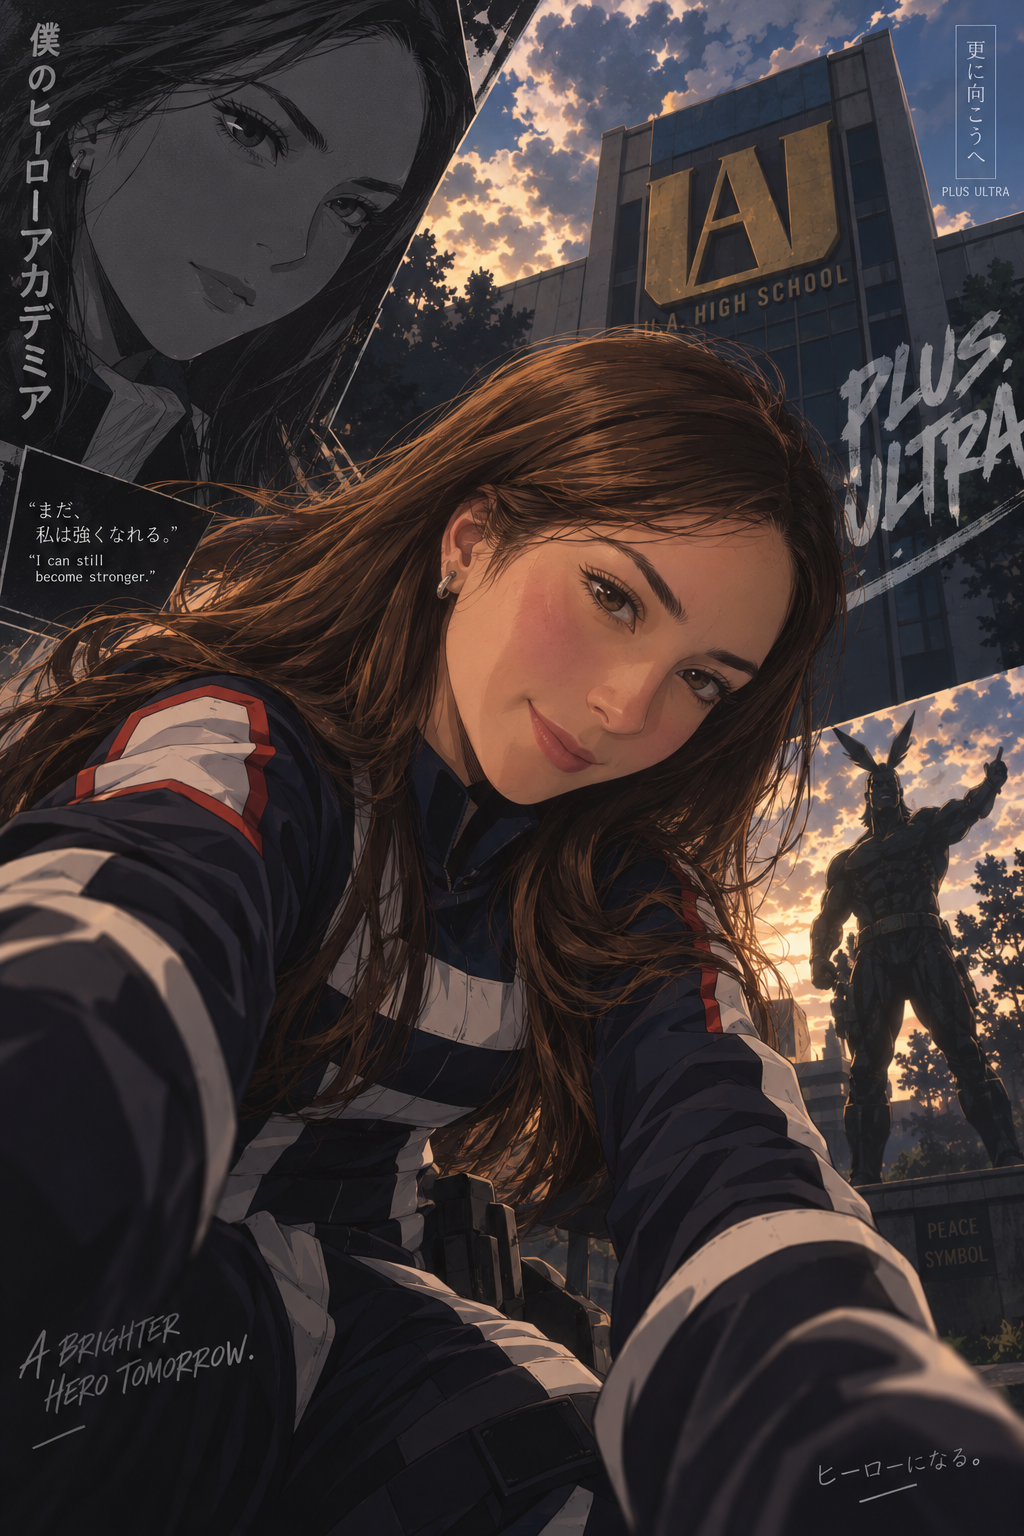

Nombre del alumno: Muñoz Meneses María Luisa

Número de control: 23210714

Correo institucional: l23210714@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')

open_system('hipertenso.slx')

parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('hipertenso', parameters);
writematrix(x.Pa,'signal.xlsx')

## Respuestas: Hipotenso, Normotenso e Hipertenso

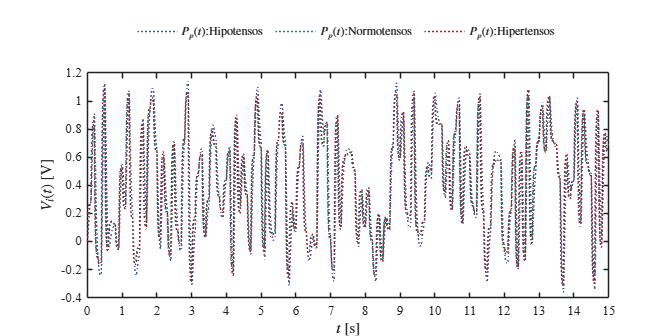

plotsignals(x.t,x.PpL, x.PpN, x.PpH, 'individuos')

## Respuesta: Hipotenso, Normotenso e Hipertenso

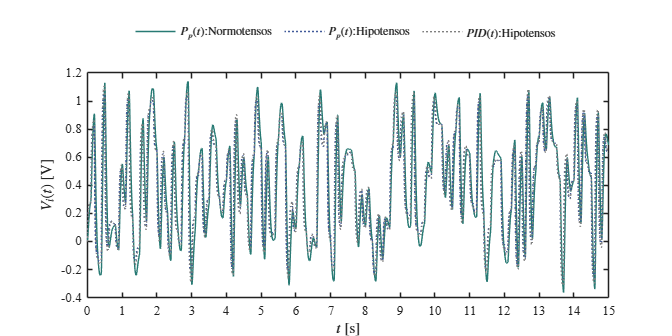

plotsignals(x.t,x.PpL, x.PpN, x.PpH, 'hipotenso')

## Respuesta:Hipotenso, Normotenso e Hipertenso

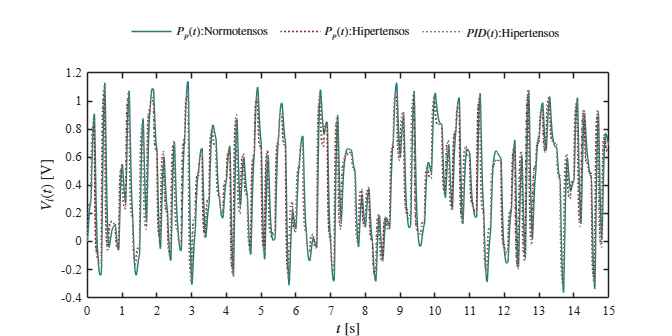



plotsignals(x.t,x.PpL, x.PpN, x.PpH, 'hipertenso')

## **Funcion: Respuestas de la simulacion **

function plotsignals(t,x1,x2,x3,caso)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',10)
hold on; grid off; box on;
clr1 = [66, 91, 154]/255;
clr2 = [40, 122, 116]/255;
clr3 = [151, 40, 40]/255;
clr4 = [0.5, 0.5, 0.5];

if caso == "individuos"
    plot(t,x1,':','LineWidth',0.25,'Color',clr1)% Hipotenso
    plot(t,x2,':','LineWidth',0.25,'Color',clr2)% Normotenso
    plot(t,x3,':','LineWidth',0.25,'Color',clr3)% Hipertenso
    L = legend('$P_p(t)$:Hipotensos','$P_p(t)$:Normotensos','$P_p(t)$:Hipertensos');
elseif caso == "hipotenso"
    plot(t,x1,'-','LineWidth',0.25,'Color',clr2)% Normotenso
    plot(t,x2,':','LineWidth',0.25,'Color',clr1)% Hipotenso
    plot(t,x3,':','LineWidth',1,'Color',clr4)% Controlador del hipotenso
    L = legend('$P_p(t)$:Normotensos','$P_p(t)$:Hipotensos','$PID(t)$:Hipotensos');
elseif caso == "hipertenso"
    plot(t,x1,'-','LineWidth',0.25,'Color',clr2)% Normotenso
    plot(t,x2,':','LineWidth',0.25,'Color',clr3)% Hipertenso
    plot(t,x3,':','LineWidth',1,'Color',clr4)% Controlador del hipertenso
    L = legend('$P_p(t)$:Normotensos','$P_p(t)$:Hipertensos','$PID(t)$:Hipertensos');
end

set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')
xlabel('$t$ [s]','interpreter','latex')
ylabel('$V_i(t)$ [V]','interpreter','latex')

xlim([0 15]); xticks(0:1:15)
ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
end 